# Data-Driven Control of an Inverted Pendulum System

Yizhak Abu, Tom Hirshberg and Alex M. Bronstein

This notebook present the proposed frame work of the paper.

- Define the system 


$$
  \dot x 
  =
  \begin{array}{cccc}
    \dot \alpha \\
    \frac{{{M} \cdot g\cdot l}}{{{I}}}\sin (\alpha ) - \frac{c}{{{I}}}\dot \alpha  + \frac{1}{I}( {\frac{{{k_t}\cdot{k_e}}}{R} + f} )\dot \theta - \frac{{{k_t}}}{{R\cdot{I}}}V \\
    - \ddot \alpha   - \frac{{{k_t}( {{k_e} + f\cdot R} )}}{{R\cdot {I_{Wheel}}}}\dot \theta+ \frac{{{k_t}}}{{R\cdot{I_{Wheel}}}}V
\end{array}
  $$


2.  Ganerate Data for the referance model

run DataGen.m

3. Train the NN-controller and save the best validation results.

run FindingNets.m

4. Stabilty Check

credit : https://github.com/heyinUCB/Stability-Analysis-using-Quadratic-Constraints-for-Systems-with-Neural-Network-Controllers

P = 	1.0e+03 *

    0.0797    0.0116   -0.0050    0.0051    0.0017   -0.0020    0.0070    0.0016   -0.0012    0.0038    0.0009   -0.0006   -0.0003
    0.0116    0.0102   -0.0030   -0.0029   -0.0014   -0.0001   -0.0013   -0.0013   -0.0000   -0.0006   -0.0011    0.0002    0.0011
   -0.0050   -0.0030    0.0061    0.0022    0.0008   -0.0013    0.0011    0.0005   -0.0009    0.0004    0.0004   -0.0009    0.0000
    0.0051   -0.0029    0.0022    0.0487    0.0060   -0.0011    0.0264    0.0033   -0.0006    0.0262    0.0043   -0.0009    0.0000
    0.0017   -0.0014    0.0008    0.0060    0.0031   -0.0005    0.0015    0.0007   -0.0003    0.0020    0.0007   -0.0004    0.0000
   -0.0020   -0.0001   -0.0013   -0.0011   -0.0005    0.0015   -0.0001   -0.0002    0.0000   -0.0003   -0.0002    0.0001   -0.0000
    0.0070   -0.0013    0.0011    0.0264    0.0015   -0.0001    0.0490    0.0065   -0.0007    0.0248    0.0042   -0.0009    0.0000
    0.0016   -0.0013    0.0005    0.0033    0.0007   -0.0002    0.0

traceP = 252.3150

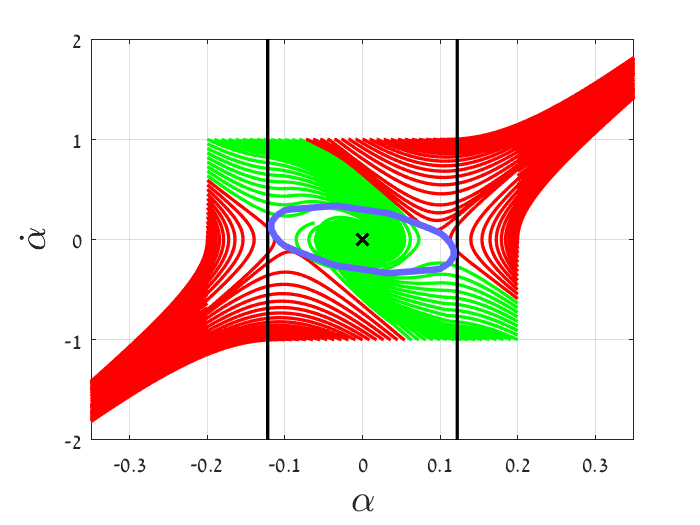

addpath('.\Inverted_Pendulum_control_saturation')
My_Pendulum_sin_local

The last state is in Lab, each controller should be tested on a real system for preformance evaluating.:

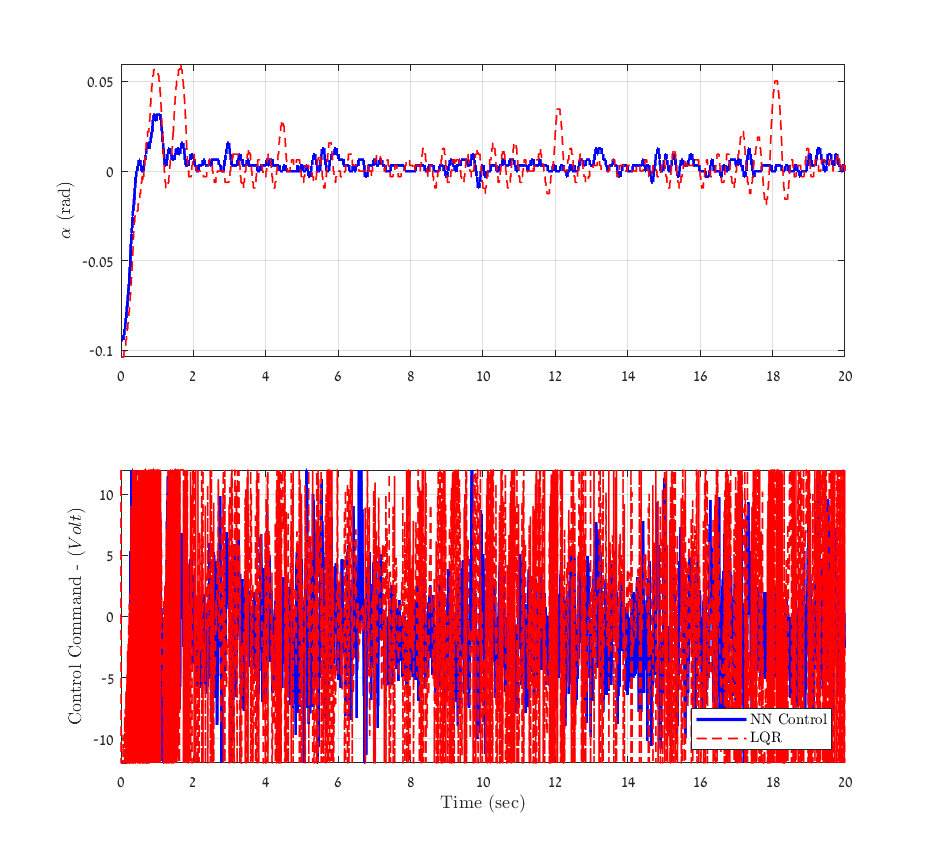

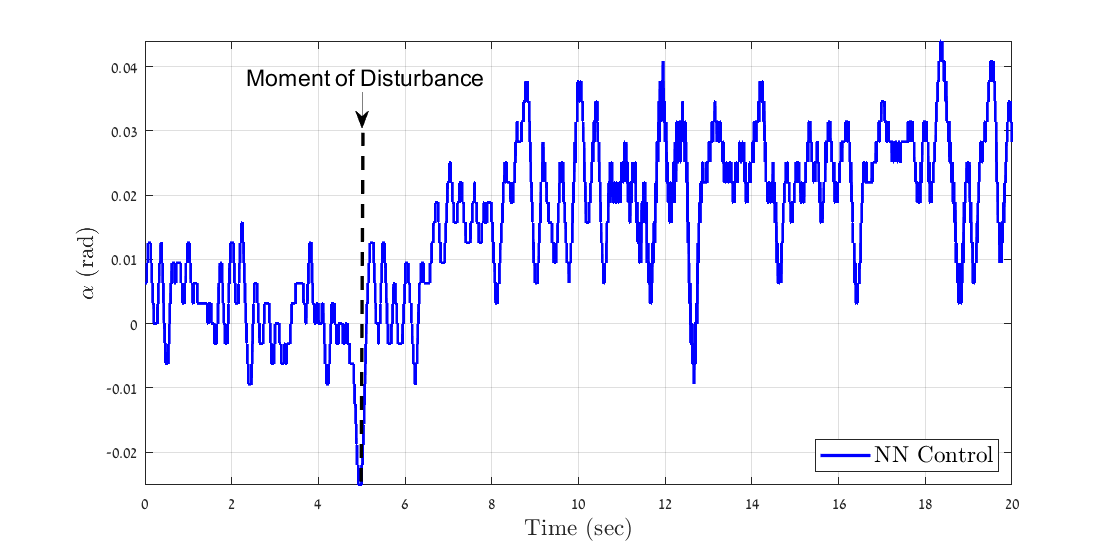

open Experimntal_Results_1.fig 
open DistrubExpAlph.fig

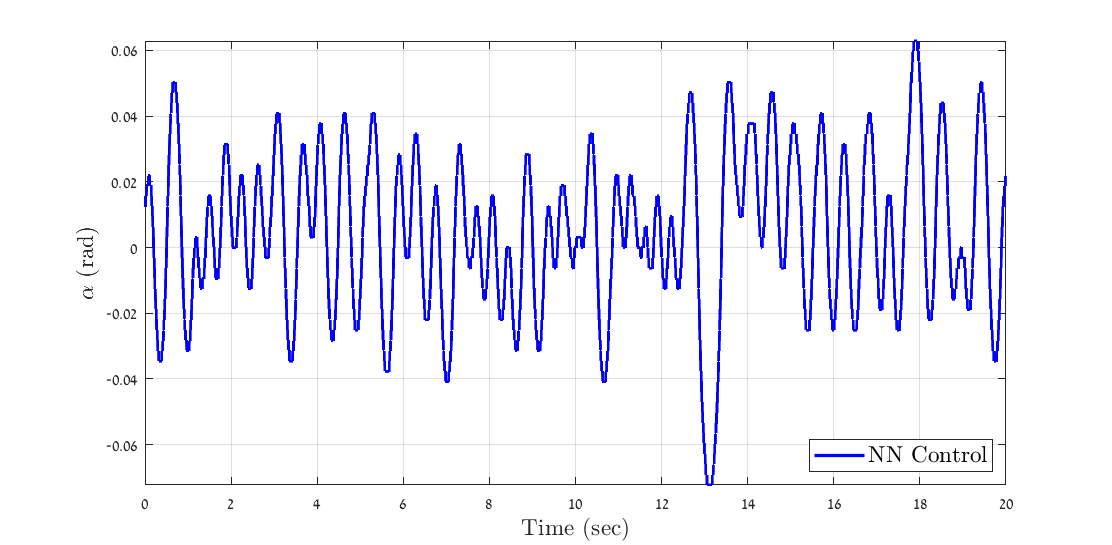

open DelayExpAlph.fig